# Deblurring using TRBGS and TRBAGS

clear;clc;close all;
addpath('.../tproduct toolbox 2.0 (transform)/')

% Define a destination folder for the figures
figsdest = '.../Real_Data_Deblurring/Deblurring_Figures';

% Import data
load mri;                               % loads mri video as order-4 tensor
X = squeeze(double(D));                 % gets rid of dimension 1 mode
X = mat2gray(X(:,:,1:12));              % takes only first 12 frames   
[m,n,p] = size(X);  

% Using Gaussian Filter

h = fspecial('gaussian',[5,5],2);       % builds a Gaussian low-pass filter
[m1,n1] = size(h);   

% Building circularly blurred images
Y = zeros(m,n,p);
for i = 1:p
    Y(:,:,i) = blurryimage(X(:,:,i), h, [m,n]);
end

% Creating a t-linear system corresponding to the deblurring problem
X_reorder = reorder_tensor(X,[m,n,p]);      % dimension n*p*m
Y_reorder = reorder_tensor(Y,[m,n,p]);

% Defining the t-linear measurement operator
A = circ_blurring_mxop(h, [m,n,p]);

% Initialization
X0 = zeros(n,p,m);
Xblurry = Y_reorder;

% Deblurring Experiments for TRGS
its = 10000;
weights = ones(its,1);

% TRBAGS
[Z_reorder_a,res_errs_a] = TRBAGS_err_deblurring(A,Y_reorder,X0,its,X_reorder,5,weights);
[Z_reorder_blurry_a,res_errs_blurry_a] = TRBAGS_err_deblurring(A,Y_reorder,Xblurry,its,X_reorder,5,weights);

% TRBGS
[Z_reorder, res_errs] = TRBGS_err_deblurring(A,Y_reorder,X0,its,X_reorder,5)

Z_reorder = Z_reorder(:,:,1) =

   1.0e-10 *

   -0.0884   -0.0418   -0.0209   -0.0211   -0.0391   -0.0582   -0.0506   -0.0504   -0.0724   -0.0816   -0.0780   -0.0770
    0.0609    0.0671    0.0677    0.0583    0.0715    0.1123    0.1360    0.1326    0.1373    0.1539    0.1599    0.1443
   -0.0222   -0.0282   -0.0424   -0.0187   -0.0125   -0.0351   -0.0444   -0.0562   -0.0624   -0.1020   -0.0958   -0.0675
   -0.0223   -0.0478   -0.0619   -0.0906   -0.0916   -0.1028   -0.1144   -0.0917   -0.0632   -0.0205   -0.0280   -0.0461
    0.0663    0.0599    0.0826    0.1013    0.0950    0.1123    0.1006    0.0888    0.0722    0.0599    0.0491    0.0506
   -0.0856   -0.0316   -0.0197   -0.0254   -0.0404   -0.0571   -0.0288   -0.0267   -0.0441   -0.0541   -0.0413   -0.0401
    0.0670    0.0427    0.0227    0.0157    0.0445    0.0797    0.0827    0.0764    0.0934    0.1039    0.1086    0.1041
   -0.0335   -0.0539   -0.0631   -0.0420   -0.0503   -0.0885   -0.1126   -0.1105   -0.1091   -0.1305   -0.1

res_errs =   182.3673  160.8698  142.8261  137.8191  121.4345  115.0071  107.2790  103.9521  103.2580  102.7694   92.4662   92.0375   83.6057   83.3740   82.8290   79.9877   75.6513   74.8982   74.8646   74.2266   73.8808   73.7013   73.3877   71.6689   70.3584   68.6093   68.0536   67.9567   67.8863   67.8618   51.4405   50.7647   50.7343   50.6967   46.9163   46.6669   46.3370   46.0395   44.8393   40.8879   40.8336   40.3878   39.8426   39.6604   39.6503   39.4905   38.9508   38.2967   37.5200   36.7567


[Z_reorder_blurry,res_errs_blurry] =  TRBGS_err_deblurring(A,Y_reorder,Xblurry,its,X_reorder,5)

Z_reorder_blurry = Z_reorder_blurry(:,:,1) =

   1.0e-10 *

    0.0339   -0.0094   -0.0163   -0.0062   -0.0469   -0.0628   -0.0483   -0.0449   -0.0603   -0.0947   -0.0967   -0.0933
   -0.0604   -0.0651   -0.0947   -0.1155   -0.0978   -0.0721   -0.0462   -0.0074   -0.0260   -0.0419   -0.0423   -0.0329
    0.0553    0.0797    0.0957    0.1061    0.1223    0.1205    0.0912    0.0603    0.0923    0.1283    0.1153    0.0992
   -0.0116   -0.0259   -0.0156    0.0128    0.0203    0.0241    0.0245    0.0462    0.0424    0.0294    0.0204    0.0262
   -0.0175    0.0186    0.0289   -0.0124   -0.0341   -0.0593   -0.0642   -0.1076   -0.1133   -0.0946   -0.0578   -0.0562
    0.0279   -0.0344   -0.0616   -0.0411   -0.0634   -0.0579   -0.0320    0.0033   -0.0096   -0.0526   -0.0716   -0.0703
   -0.0503   -0.0268   -0.0350   -0.0475   -0.0063    0.0255    0.0245    0.0449    0.0477    0.0612    0.0522    0.0554
    0.0600    0.0957    0.1281    0.1443    0.1453    0.1213    0.0846    0.0350    0.0642   

res_errs_blurry =   182.3673  172.7158  165.6880  158.9924  140.3211  129.3355  110.4692  106.1112   99.7266   98.6113   96.7037   92.5413   91.8355   90.3285   77.6969   77.6729   63.8174   58.5138   58.4705   57.5597   51.3282   50.2801   49.3631   48.4787   38.2505   37.4417   37.1982   37.0522   36.5225   36.4222   35.1112   34.4603   33.2313   33.1119   32.9300   32.5309   32.1284   31.3430   31.1678   31.0992   30.8458   30.7192   30.0715   30.0394   29.8857   29.5405   29.5125   29.3821   29.3503   29.2331



Z_a = recover_img(Z_reorder_a,[m,n,p]);
Z_blurry_a = recover_img(Z_reorder_blurry_a,[m,n,p]);

Z = recover_img(Z_reorder,[m,n,p]);
Z_blurry = recover_img(Z_reorder_blurry,[m,n,p]);

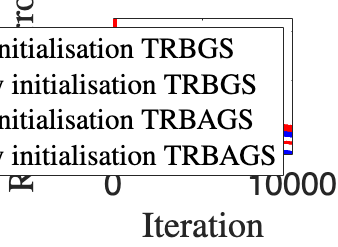

figure(1);
% TRBAGS plots
h1a = semilogy(0:its,res_errs_a,'b--','LineWidth',4);
hold on
h2a = semilogy(0:its,res_errs_blurry_a,'b-','LineWidth',4);
hold on

% TRBGS plots
h1 = semilogy(0:its,res_errs,'r--','LineWidth',2);
hold on
h2 = semilogy(0:its,res_errs_blurry,'r-','LineWidth',4);
hold off

xlabel('Iteration','FontSize',28,'Interpreter','latex') 
ylabel('Residual Error','FontSize',28,'Interpreter','latex') 
legend([h1(1),h2(1),h1a(1),h2a(1)],{'zero initialisation TRBGS', 'blurry initialisation TRBGS','zero initialisation TRBAGS', 'blurry initialisation TRBAGS'},'FontSize',16,'Interpreter','latex','Location','northeast')

set(gcf,'position',[10,10,550,400])
set(gca,'FontSize',18)
savefig(fullfile(figsdest,'TBRGS_deblurring_error_diff_initialization.fig'))
saveas(gca,fullfile(figsdest,'TBRGS_deblurring_error_diff_initialization.png'))

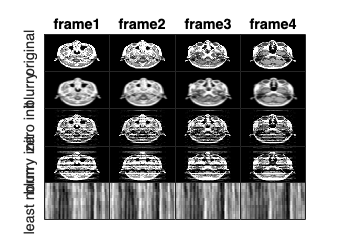

clear res_errs res_errs_a res_errs_blurry res_errs_blurry_a
clear Z_reorder_blurry Z_reorder_blurry_a Z_reorder Z_reorder_a
clear X_reorder Y_reorder

X_ln = tprod(tpinv(A),reorder_tensor(Y,[m,n,p]));
clear A

t = tiledlayout(5,4,'TileSpacing','none');

for i = 1:4
    nexttile;
    imagesc(X(:,:,i),[0,1]); % colormap gray
    title(sprintf('frame%d',i), 'FontSize',8)
    if i == 1
        ylabel("original",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Y(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z(:,:,i),[0,1]); % colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("zero init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_blurry(:,:,i),[0,1]); % colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

% Calculate least-norm solution
for i = 1:4
    nexttile;
    imagesc(permute(X_ln(:,:,i),[2,1,3]));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("least norm",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 8 12]); % x_width=10cm, y_width=15cm

savefig(fullfile(figsdest,'TRBGSdeblurring_diff_initialization.fig'))
saveas(gcf,fullfile(figsdest,'TRBGSdeblurring_diff_initialization.png'))

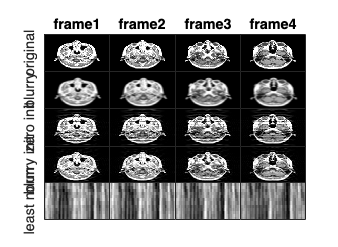

ta = tiledlayout(5,4,'TileSpacing','none');

for i = 1:4
    nexttile;
    imagesc(X(:,:,i),[0,1]); % Colormap gray
    title(sprintf('frame%d',i), 'FontSize',8)
    if i == 1
        ylabel("original",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Y(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_a(:,:,i),[0,1]); % Colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("zero init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_blurry_a(:,:,i),[0,1]); % Colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

% Calculate least-norm solution
for i = 1:4
    nexttile;
    imagesc(permute(X_ln(:,:,i),[2,1,3]));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("least norm",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 8 12]); % x_width=10cm, y_width=15cm

savefig(fullfile(figsdest,'TRBAGSdeblurring_diff_initialization.fig'))
saveas(gcf,fullfile(figsdest,'TRBAGSdeblurring_diff_initialization.png'))